Estoy probando a utilizar los pesos a cada layer (encontré los pesos en el paper)

clc; clear all; close all;

img_path = fullfile('Codes','OD_circle_SQ_9_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

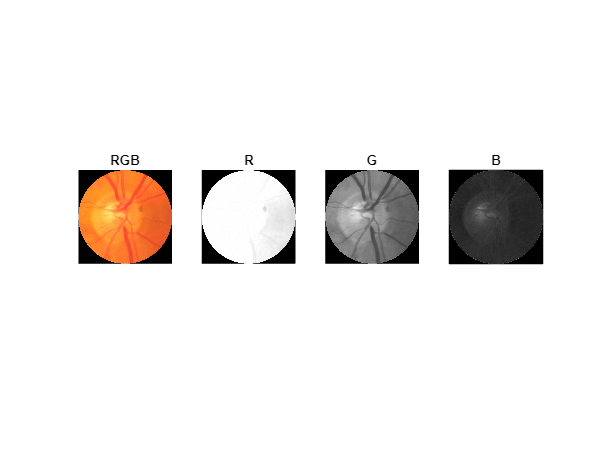

RGB = imread(string(fullfile(img_path, T{32,1})));%Aquí elijes la imagen
R=RGB(:,:,1);
G=RGB(:,:,2);
B=RGB(:,:,3);
figure;
subplot(1, 4, 1);
imshow(RGB);
title('RGB');
subplot(1, 4, 2);
imshow(R);
title('R');
subplot(1, 4, 3);
imshow(G);
title('G');
subplot(1, 4, 4);
imshow(B);
title('B');

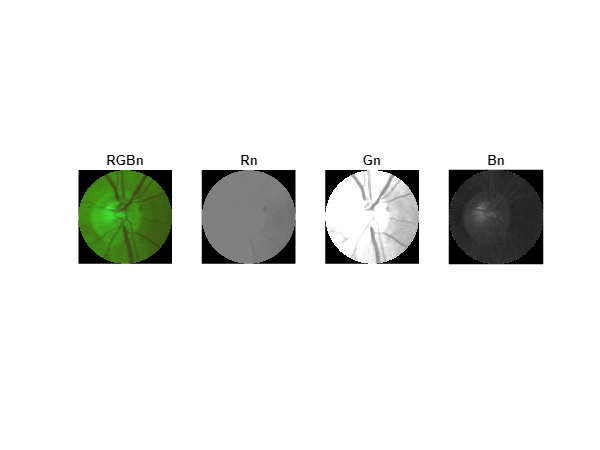

R=double(R);
G=double(G);
B=double(B);
Rn=R.*0.5;
Gn=G.*2;
Bn=B.*1;
RGBn = cat(3, Rn, Gn, Bn);
RGBn = RGBn./2;
RGBn=uint8(RGBn);
figure;
subplot(1, 4, 1);
imshow(uint8(RGBn));
title('RGBn');
subplot(1, 4, 2);
imshow(uint8(Rn));
title('Rn');
subplot(1, 4, 3);
imshow(uint8(Gn));
title('Gn');
subplot(1, 4, 4);
imshow(uint8(Bn));
title('Bn');

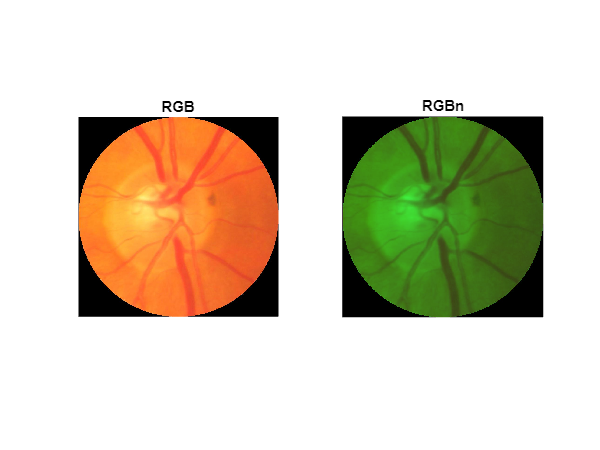

figure;
subplot(1, 2, 1);
imshow(RGB);
title('RGB');
subplot(1, 2, 2);
imshow(uint8(RGBn));
title('RGBn');

## **PROBANDO SUPERPIXEL**

Hago el superpixel grouping pa cada uno de ellos:

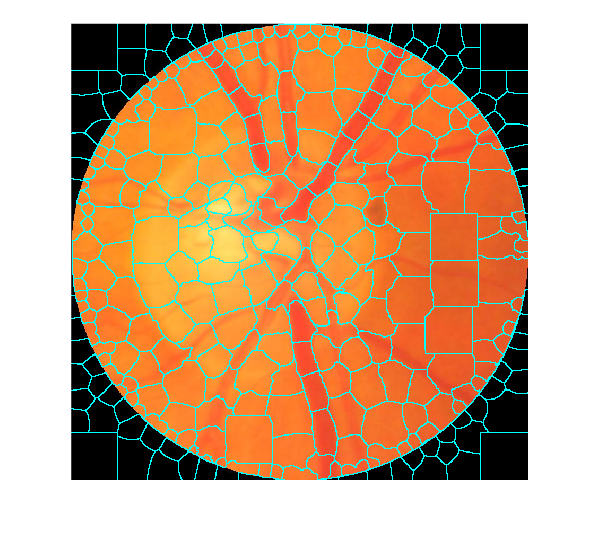

superpixelQuantity=400;
[L,N] = superpixels(RGB,superpixelQuantity, "NumIterations",150,"Compactness",1);

figure;
BW = boundarymask(L);
figure;
imshow(imoverlay(RGB,BW,'cyan'),'InitialMagnification',67);

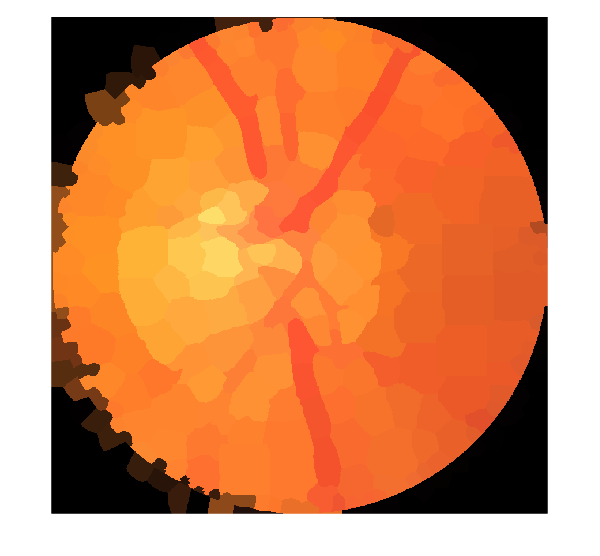


outputImage = zeros(size(RGB),'like',RGB);
idx = label2idx(L);
numRows = size(RGB,1);
numCols = size(RGB,2);
for labelVal = 1:N
    redIdx = idx{labelVal};
    greenIdx = idx{labelVal}+numRows*numCols;
    blueIdx = idx{labelVal}+2*numRows*numCols;
    outputImage(redIdx) = mean(RGB(redIdx));
    outputImage(greenIdx) = mean(RGB(greenIdx));
    outputImage(blueIdx) = mean(RGB(blueIdx));
end    

figure
imshow(outputImage)

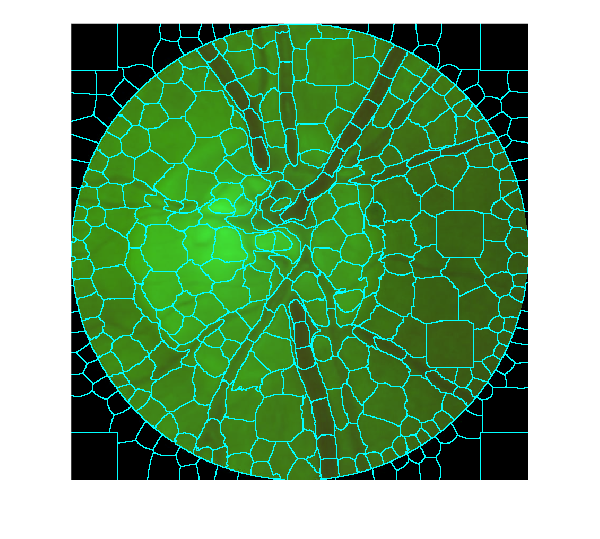


[L,N] = superpixels(RGBn,superpixelQuantity, "NumIterations",150,"Compactness",1);

figure;
BW = boundarymask(L);
figure;
imshow(imoverlay(RGBn,BW,'cyan'),'InitialMagnification',67);

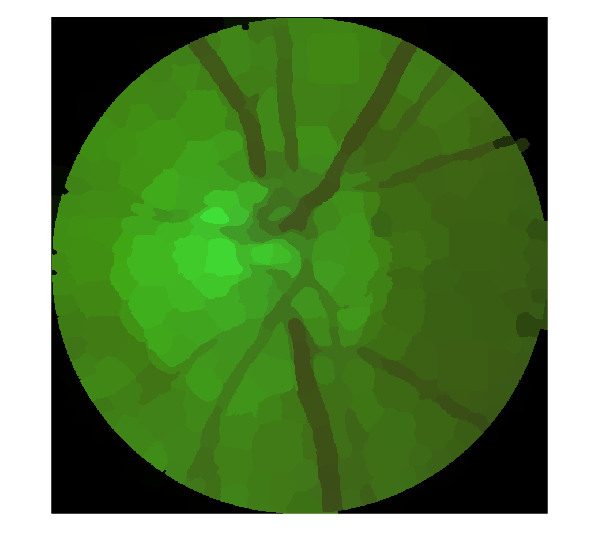


outputImage = zeros(size(RGBn),'like',RGBn);
idx = label2idx(L);
numRows = size(RGBn,1);
numCols = size(RGBn,2);
for labelVal = 1:N
    redIdx = idx{labelVal};
    greenIdx = idx{labelVal}+numRows*numCols;
    blueIdx = idx{labelVal}+2*numRows*numCols;
    outputImage(redIdx) = mean(RGBn(redIdx));
    outputImage(greenIdx) = mean(RGBn(greenIdx));
    outputImage(blueIdx) = mean(RGBn(blueIdx));
end    

figure
imshow(outputImage)

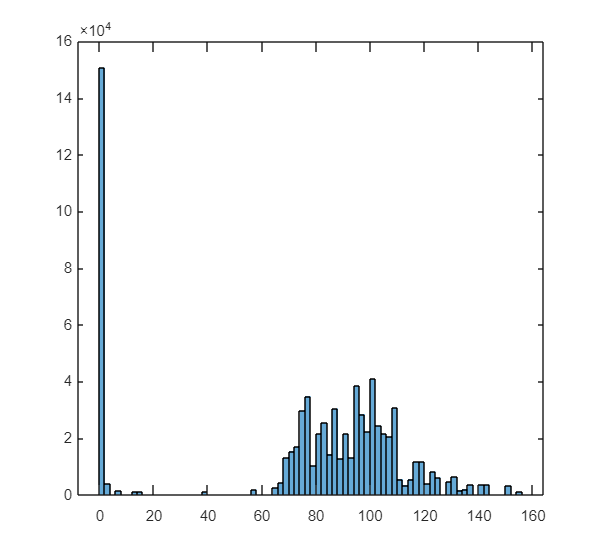

Ig=rgb2gray(outputImage);
histogram(Ig);

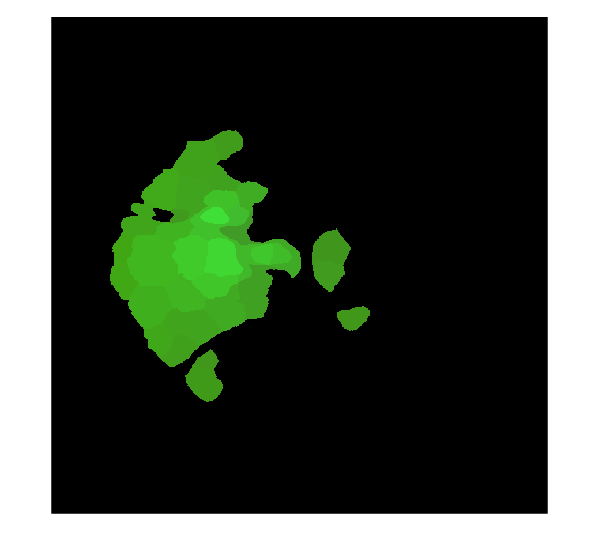


thres=Ig>0.7*max(Ig(:));
out_thresed=double(outputImage).*thres;
imshow(uint8(out_thresed));

%EN EL 9 HA FUNCIONADO PERO NO ES UN MÉTODO EFECTIVO PARA USAR EN GENERAL
%EN UN CÓDIGO.

PROBANDO A BUSCAR CÍRCULOS** Me pilla demasiados así qeu le tendré que hacer un preproccesing o algo**

figure;
imshow(outputImage);
stats = regionprops("table",double(rgb2gray(outputImage)),"Centroid", ...
    "MajorAxisLength","MinorAxisLength","Orientation","Eccentricity")

stats = 156×5 table
        Centroid        MajorAxisLength    MinorAxisLength    Eccentricity    Orientation
    ________________    _______________    _______________    ____________    ___________

    399.55    444.26        1305.3             1210.2           0.37463         -76.566  
    193.54    586.57        1292.5             425.73           0.94419          85.093  
    5.8189    523.35        54.708             12.884           0.97187          -84.21  
       NaN       NaN             0                  0                 0               0  
       NaN       NaN             0                  0                 0               0  
    14.491    283.03        59.555             33.629           0.82532          85.682  
       NaN       NaN             0                  0                 0               0  

stats( stats.MajorAxisLength > 670 | stats.MajorAxisLength < 650 , : ) = []%he puesto esta linea que la he sacado de otro código, está 100x100 mal. Hay que poner and en vez de or!!!!!

stats = 1×5 table
        Centroid        MajorAxisLength    MinorAxisLength    Eccentricity    Orientation
    ________________    _______________    _______________    ____________    ___________

    360.08    433.93        669.57             444.02           0.74849         -58.45   


centers = stats.Centroid;
diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;
hold on
viscircles(centers,radii)%aquí busca una manera de poder dibujar elipses en vez de circulos

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


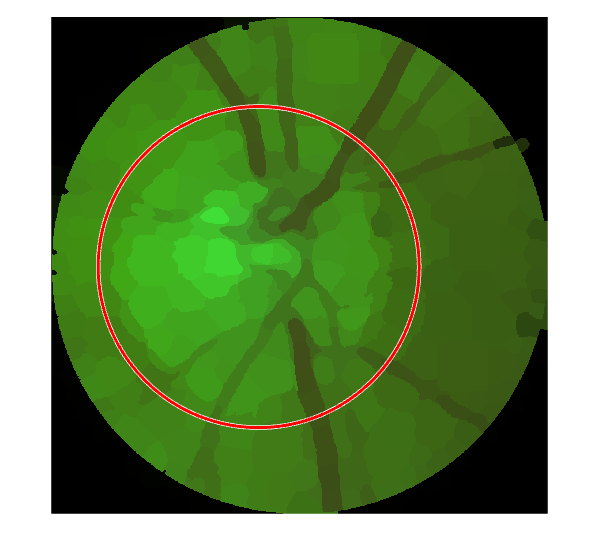

hold off

lat0 = centers(2);
lon0 = centers(1);
semimajor = stats.MajorAxisLength;
ecc = axes2ecc(semimajor,stats.MinorAxisLength);
[lat1,lon1] = ellipse1(lat0,lon0,[semimajor ecc]);
idx = find([stats.MajorAxisLength] > 650 & [stats.MajorAxisLength] < 670); 
%BW2 = ismember(labelmatrix(cc),idx);  

Unrecognized function or variable 'cc'.

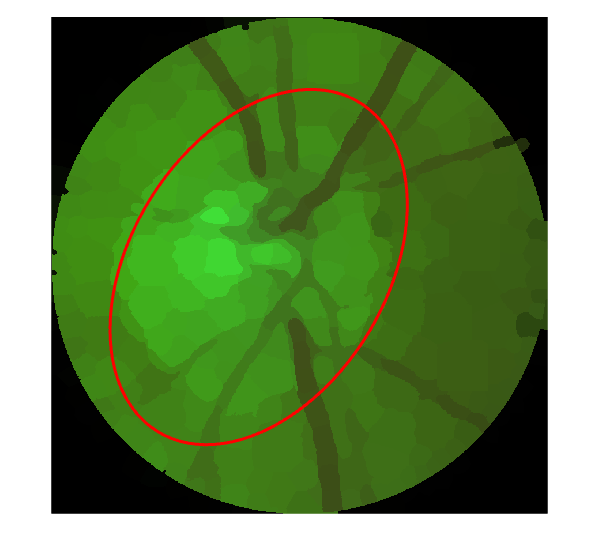

% Crear una matriz de coordenadas para la elipse
theta = linspace(0, 2*pi, 100);
if stats.Orientation<0;
    orientation=stats.Orientation+180;
end
x = centers(1) + stats.MajorAxisLength/2 * cos(theta) * cosd(orientation) - stats.MinorAxisLength/2 * sin(theta) * sind(orientation);
y = centers(2) + stats.MajorAxisLength/2 * cos(theta) * sind(orientation) + stats.MinorAxisLength/2 * sin(theta) * cosd(orientation);

% Mostrar la imagen y dibujar la elipse encima
imshow(outputImage);
hold on;
plot(x, y, 'r', 'LineWidth', 2);
hold off;